# Lab 02 Fourier Decomposition

% clear the workspace
clear
close all
clc
clf

% set tuid and amplitude
tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]



## Part 1

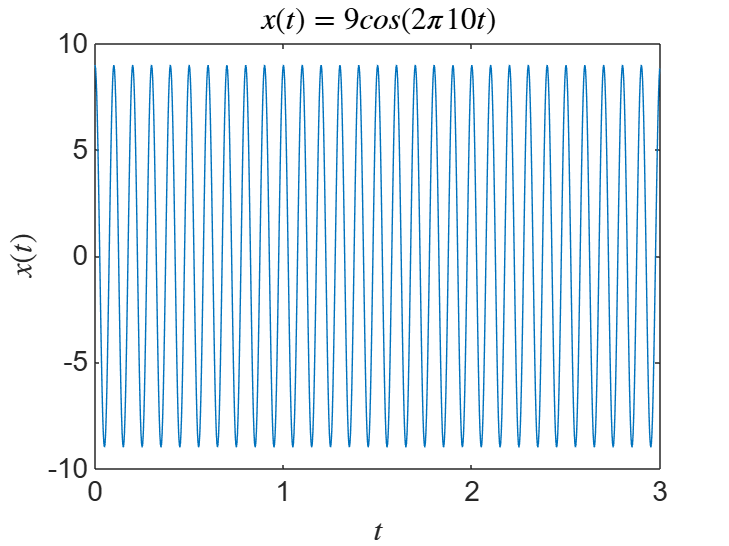

%% generating original cosine signal
fc = 10; % Frequency                                   
fs = 32*fc; % Sampling frequecny
T = 1/fc;   % Time period
Ts = 1/fs;  % Sampling Interval
phase = 0; % Phase

t = 0:Ts:3-Ts; % 2 seconds duartion
x = A*cos(2*pi*fc*t+phase); 


plot(t,x)
set(gca,'fontsize',16)
title('$x(t)=9cos(2 \pi 10 t)$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

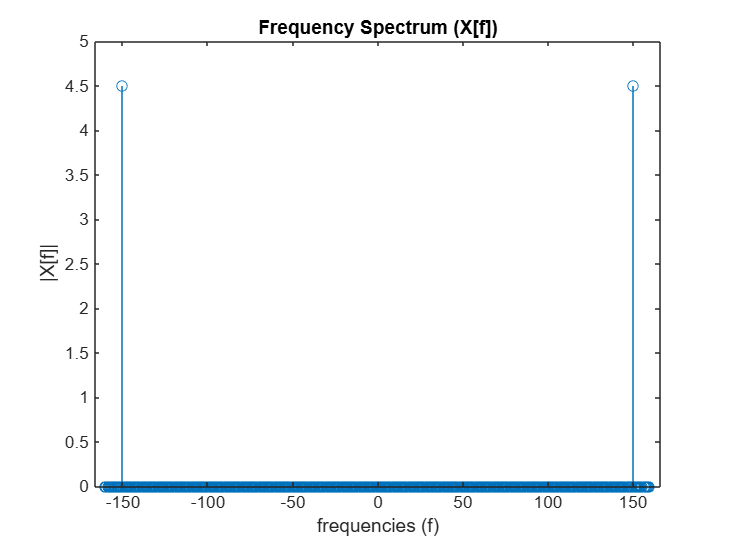


% Generating the amplitude spectrum
% FFTShift 
N = 512;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;

% Generating the frequency spectrum
stem(f,abs(X))
title('Frequency Spectrum (X[f])')
xlabel('frequencies (f)')
ylabel('|X[f]|')

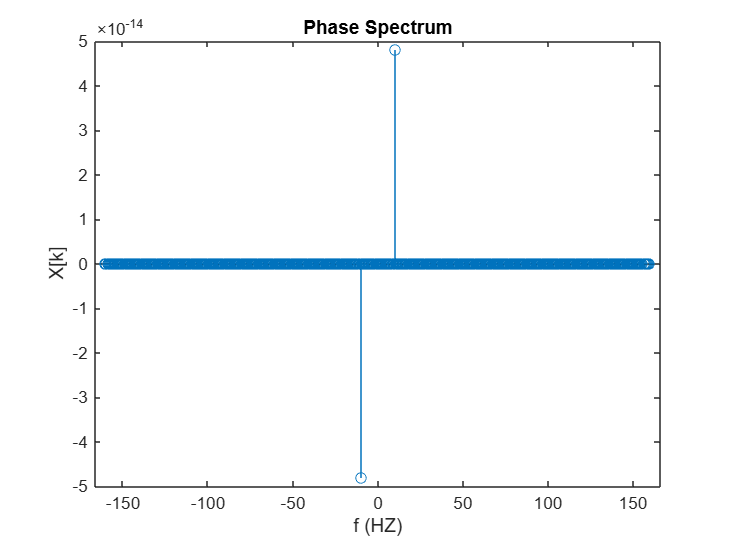


% Generating Phase spectrum
X2 = X1;
tol = max(abs(X1));
X2(abs(X1)<tol) = 0;
phase1 = atan2(imag(X2),real(X2));

stem(f,rad2deg(phase1))
ylabel('X[k]')
xlabel('f (HZ)')
title('Phase Spectrum')

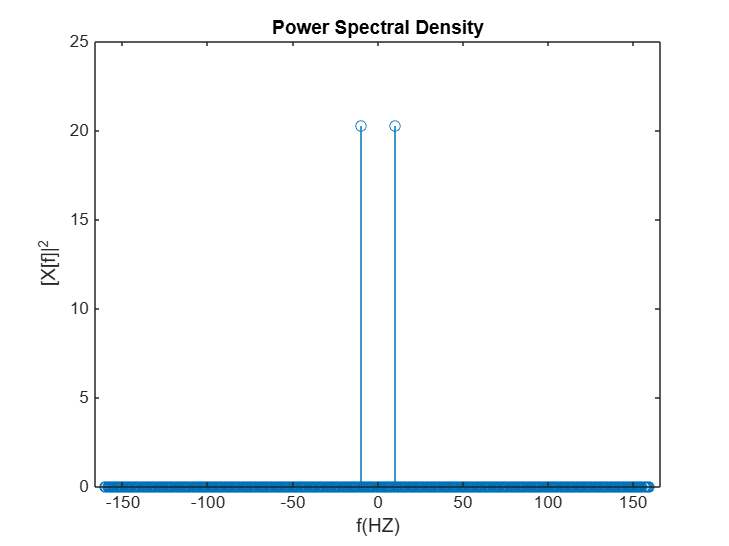


% Generating Power Spectral Density
stem(f,abs(X1).^2)
xlabel('f(HZ)')
ylabel('[X[f]|^2')
title('Power Spectral Density')

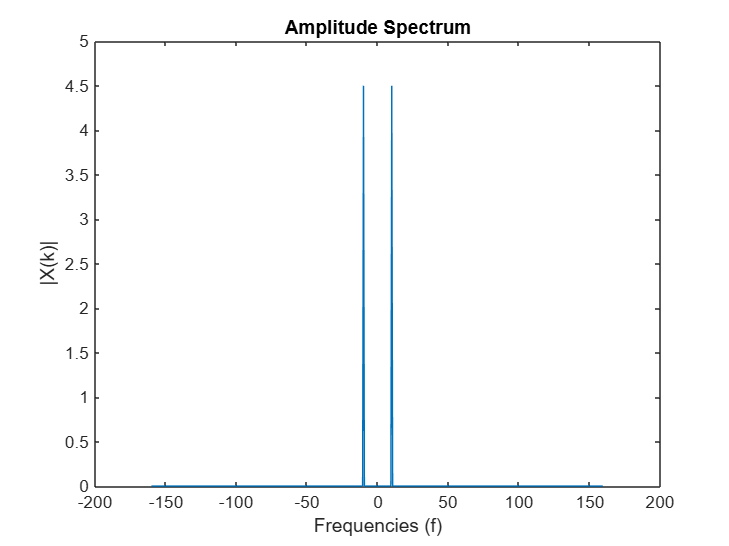


plot(f,abs(X1))
title('Amplitude Spectrum')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

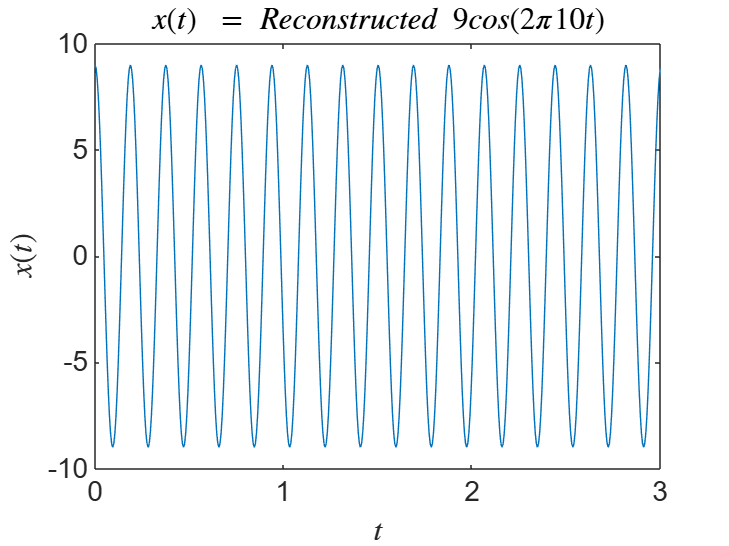


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

## Part 2

%% generating original cosine signal
fc = 10; % Frequency                                   
fs = 32*fc; % Sampling frequecny
T = 1/fc;   % Time period
Ts = 1/fs;  % Sampling Interval
phase = 0; % Phase

t = 0:Ts:3-Ts; % 2 seconds duartion
x = A*cos(2*pi*fc*t+phase); 


plot(t,x)
set(gca,'fontsize',16)
title('$x(t)=9cos(2 \pi 10 t)$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

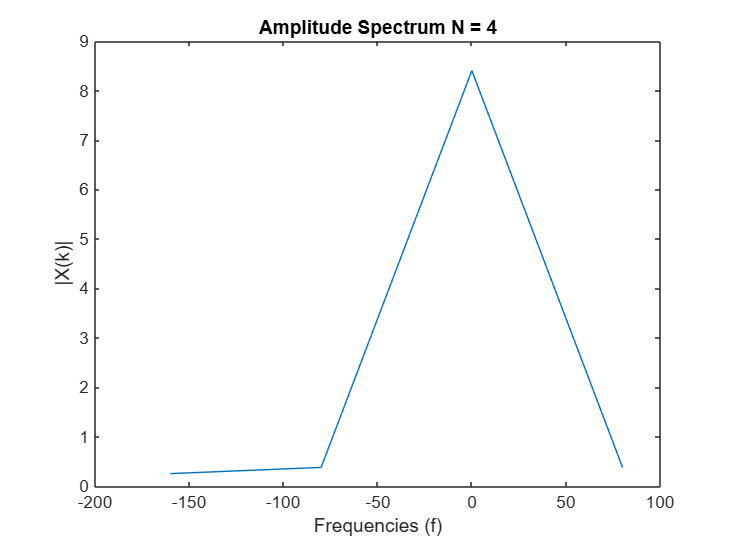


% Generating the amplitude spectrum
% FFTShift 
N = 4;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;

plot(f,abs(X1))
title('Amplitude Spectrum N = 4')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

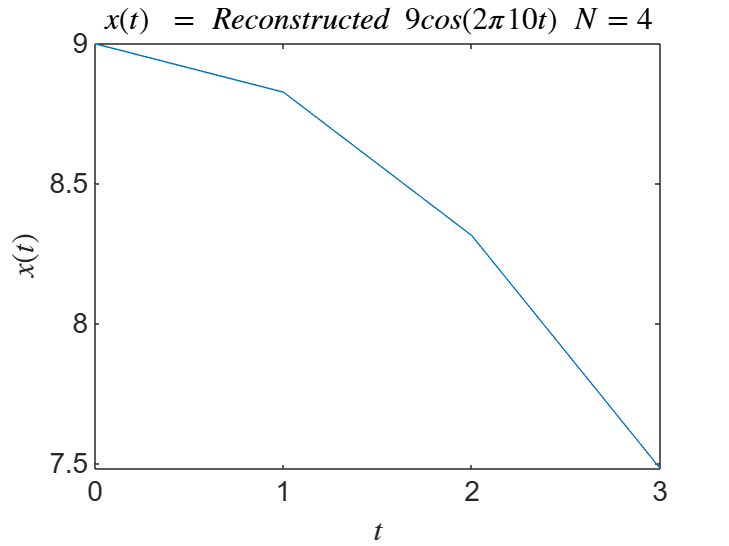


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 4$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

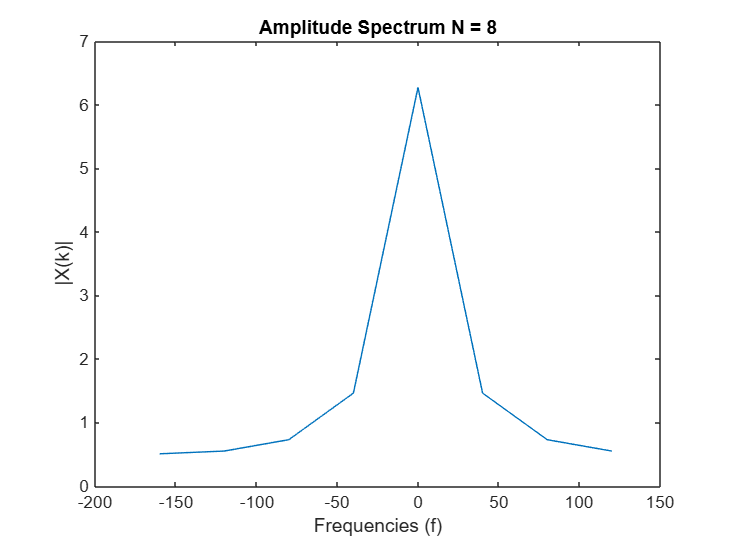


% Generating the amplitude spectrum
% FFTShift 
N = 8;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;


plot(f,abs(X1))
title('Amplitude Spectrum N = 8')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

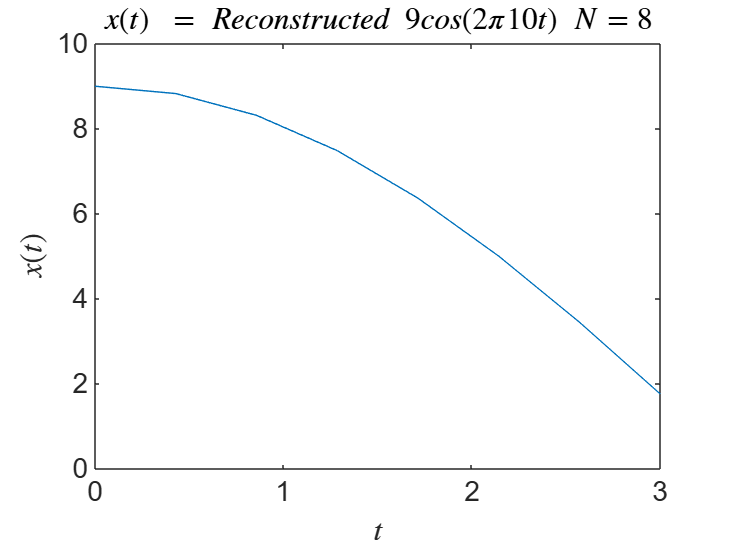


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 8$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

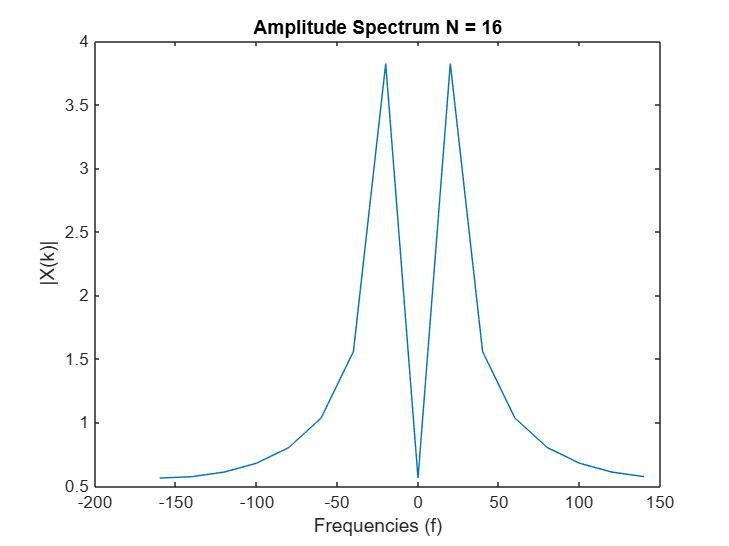


% Generating the amplitude spectrum
% FFTShift 
N = 16;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;


plot(f,abs(X1))
title('Amplitude Spectrum N = 16')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

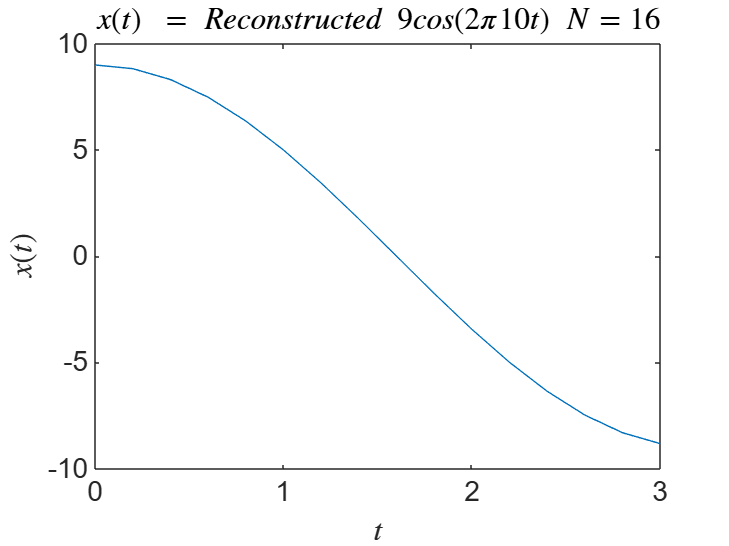


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 16$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

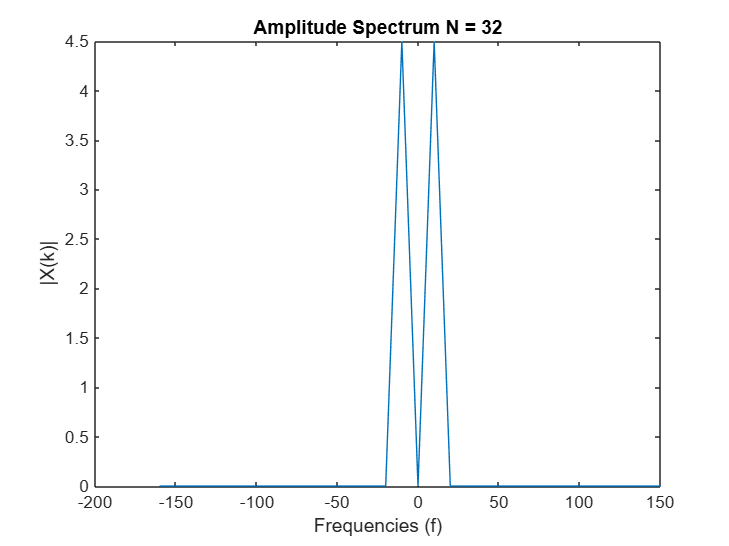


% Generating the amplitude spectrum
% FFTShift 
N = 32;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;


plot(f,abs(X1))
title('Amplitude Spectrum N = 32')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

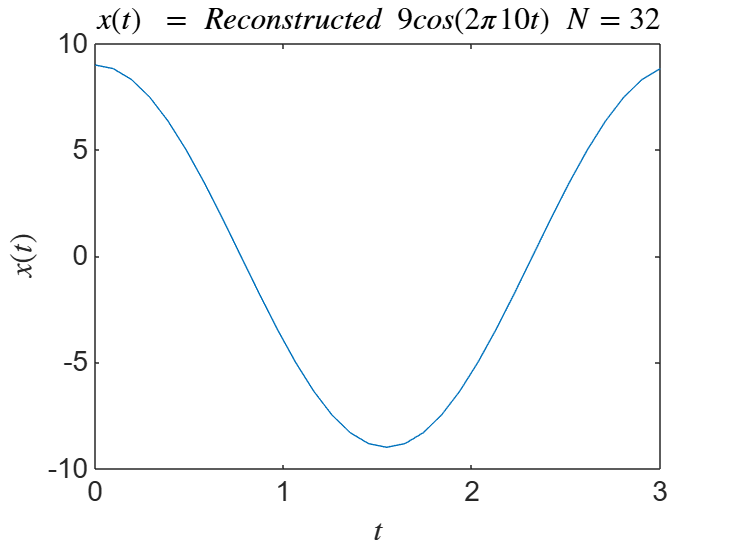


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 32$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

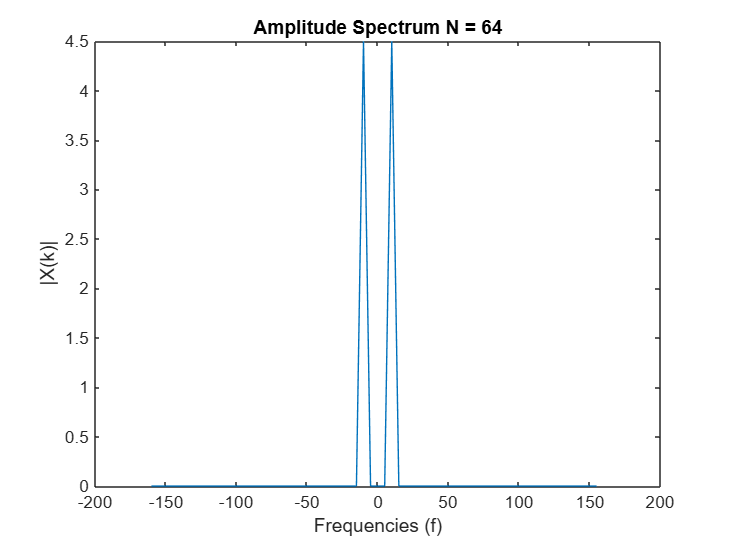


% Generating the amplitude spectrum
% FFTShift 
N = 64;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;


plot(f,abs(X1))
title('Amplitude Spectrum N = 64')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

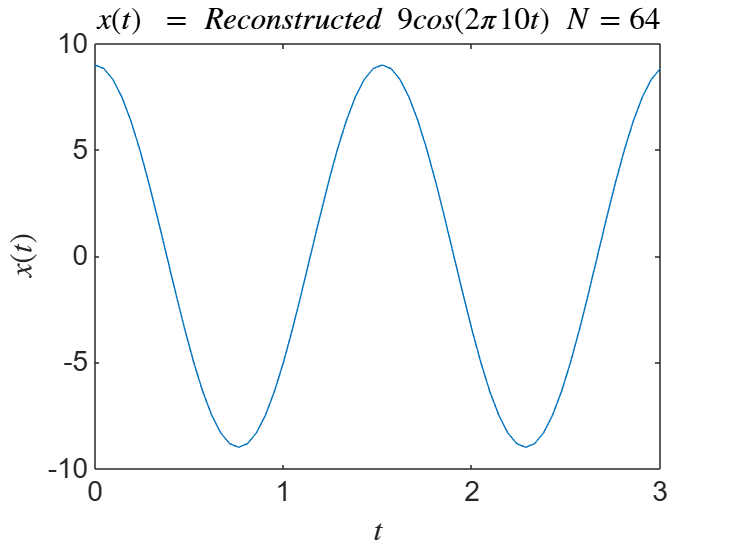


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 64$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

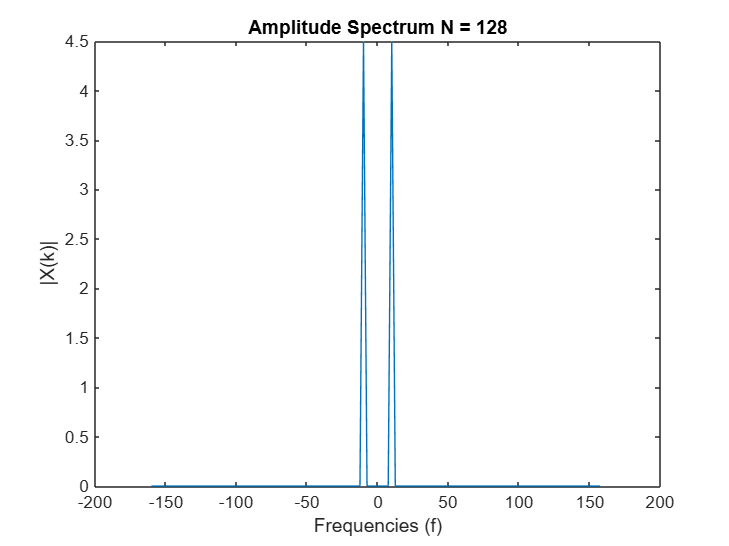


% Generating the amplitude spectrum
% FFTShift 
N = 128;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;

plot(f,abs(X1))
title('Amplitude Spectrum N = 128')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

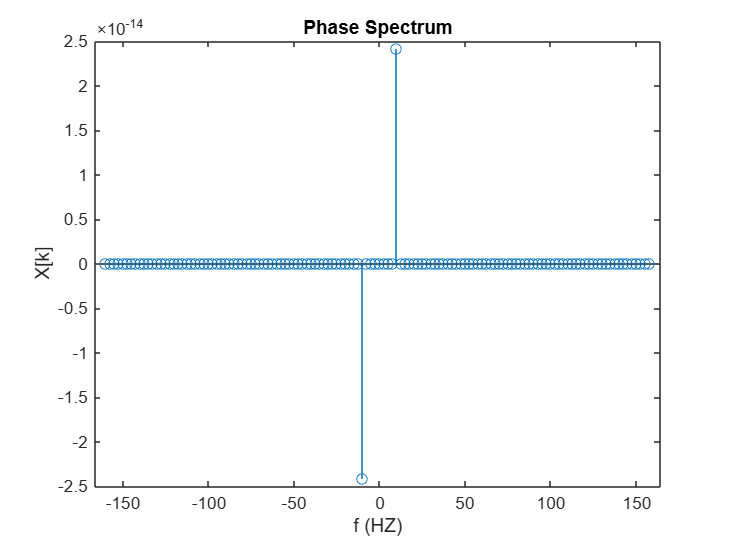


% Generating the phase spectrum
X2 = X1;
tol = max(abs(X1));
X2(abs(X1)<tol) = 0;
phase1 = atan2(imag(X2),real(X2));

figure(6)
stem(f,rad2deg(phase1))
ylabel('X[k]')
xlabel('f (HZ)')
title('Phase Spectrum')

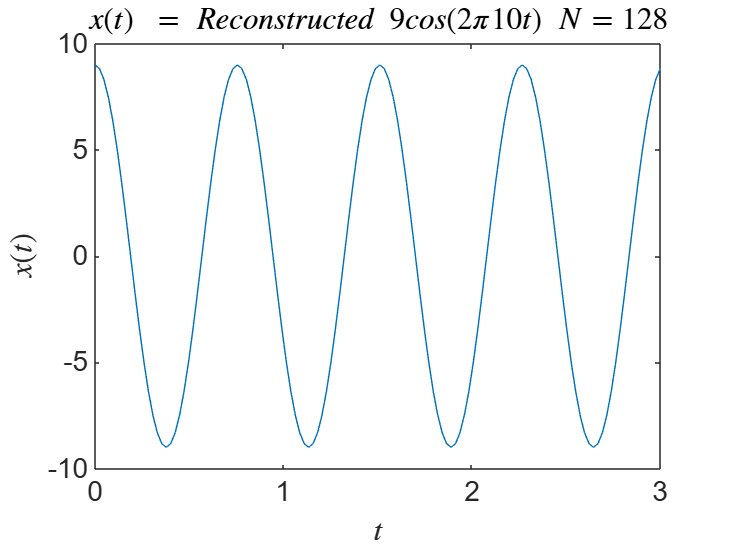


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 128$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

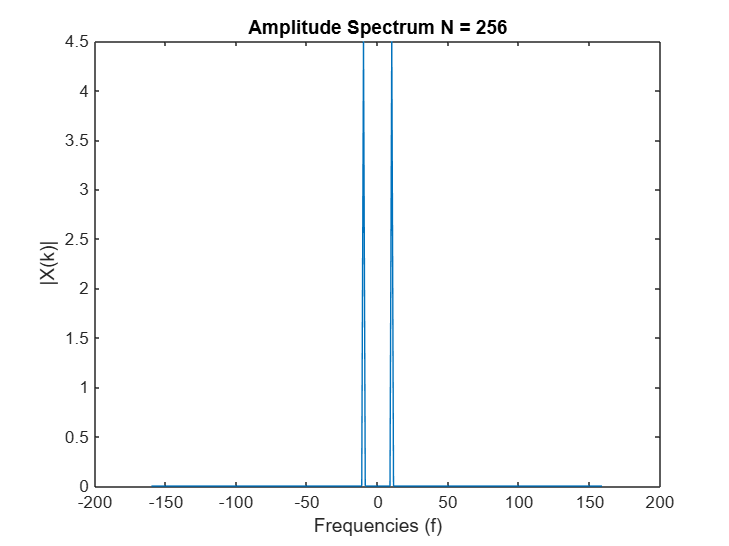


% Generating the amplitude spectrum
% FFTShift 
N = 256;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;


plot(f,abs(X1))
title('Amplitude Spectrum N = 256')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

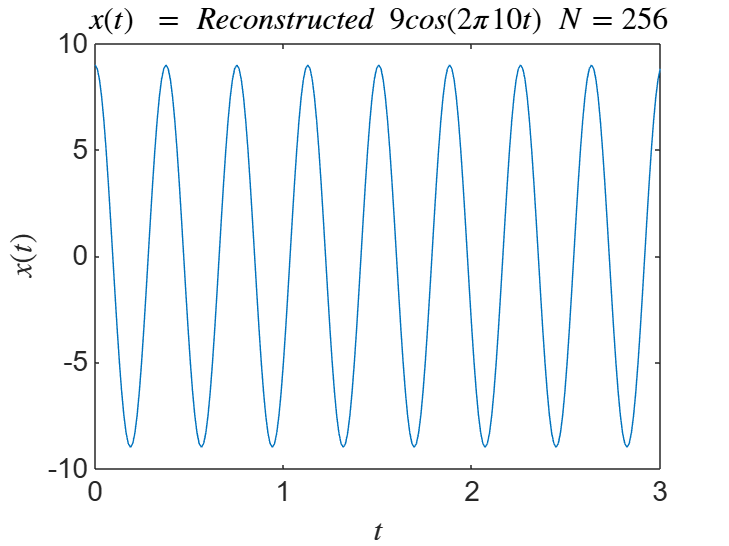


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t)\ N = 256$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

## Part 3

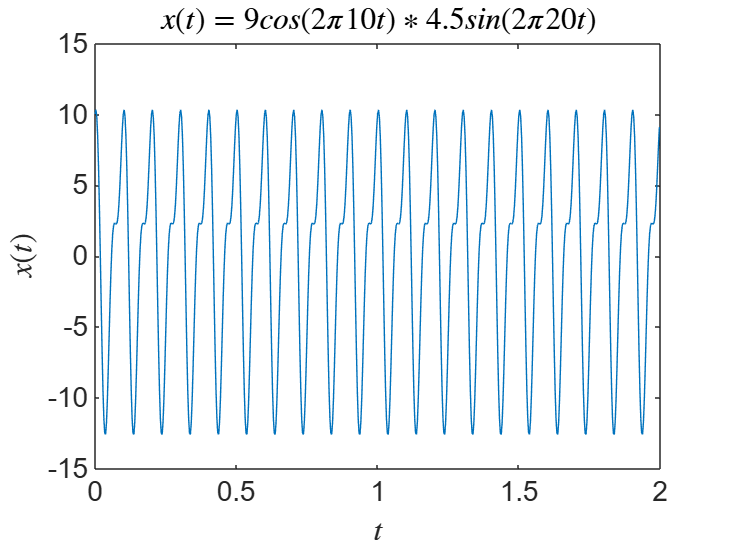

%% generating original cosine signal
fc = 10; % Frequency                                   
fs = 32*fc; % Sampling frequecny
fm = 20;
T = 1/fc;   % Time period
Ts = 1/fs;  % Sampling Interval
phase = pi/6; % Phase

t = 0:Ts:2-Ts; % 2 seconds duartion
x = A * cos(2*pi*fc*t+phase) + .5 * A * sin(2*pi*fm*t+phase); 

plot(t,x)
set(gca,'fontsize',16)
title('$x(t)=9cos(2 \pi 10 t) * 4.5sin(2 \pi 20 t)$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

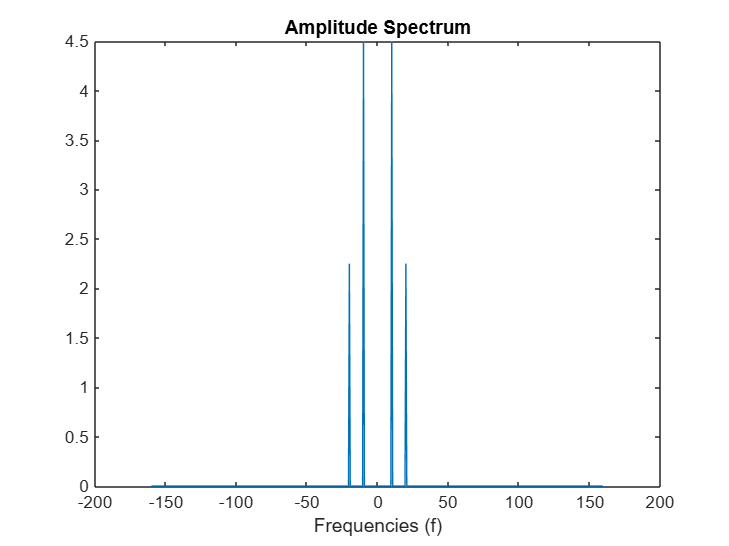


% Generating the amplitude spectrum
% FFTShift 
N = 512;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;

plot(f,abs(X1))
title('Amplitude Spectrum')
xlabel('Frequencies (f)')

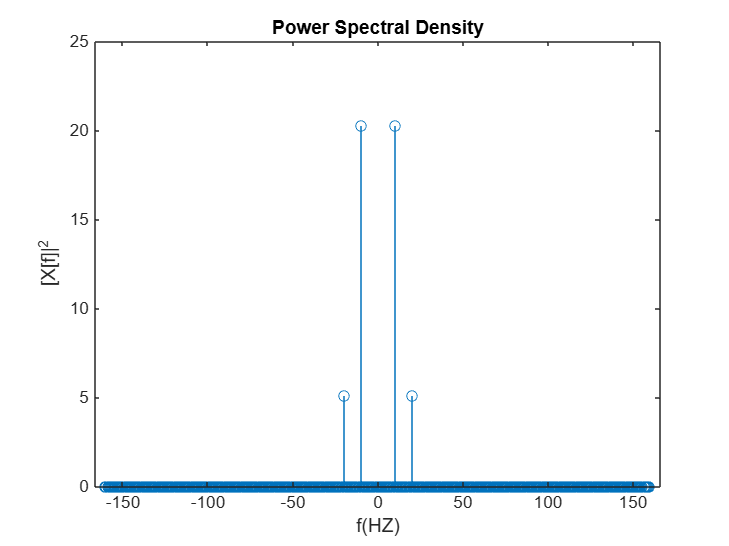


% Generating the power spectral density
stem(f,abs(X1).^2)
xlabel('f(HZ)')
ylabel('[X[f]|^2')
title('Power Spectral Density')

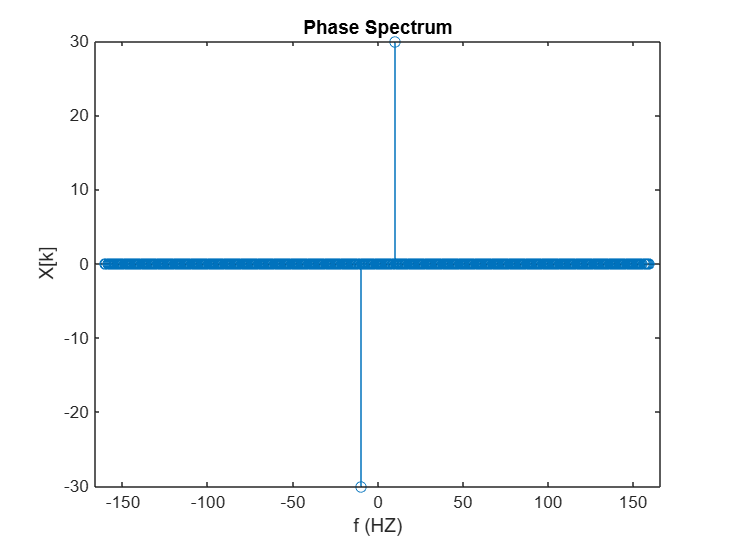



% Generating the phase spectrum
X2 = X1;
tol = max(abs(X1));
X2(abs(X1)<tol) = 0;
phase1 = atan2(imag(X2),real(X2));

stem(f,rad2deg(phase1))
ylabel('X[k]')
xlabel('f (HZ)')
title('Phase Spectrum')

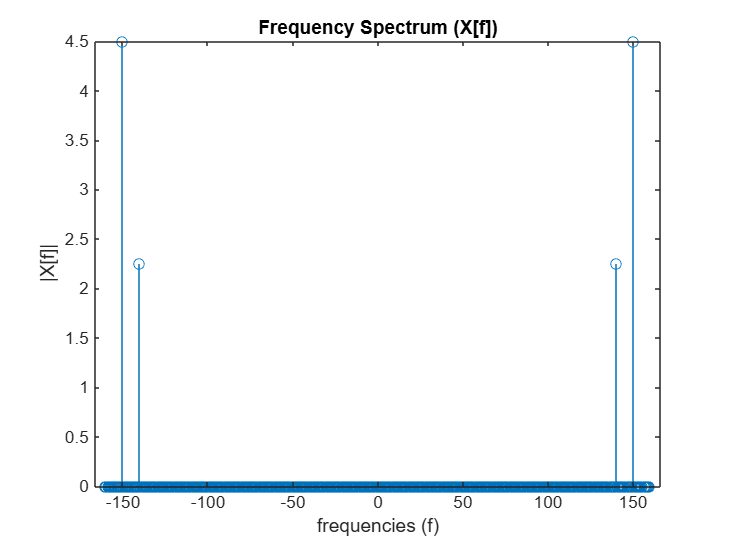


% Generating the frequency spectrum
stem(f,abs(X))
title('Frequency Spectrum (X[f])')
xlabel('frequencies (f)')
ylabel('|X[f]|')

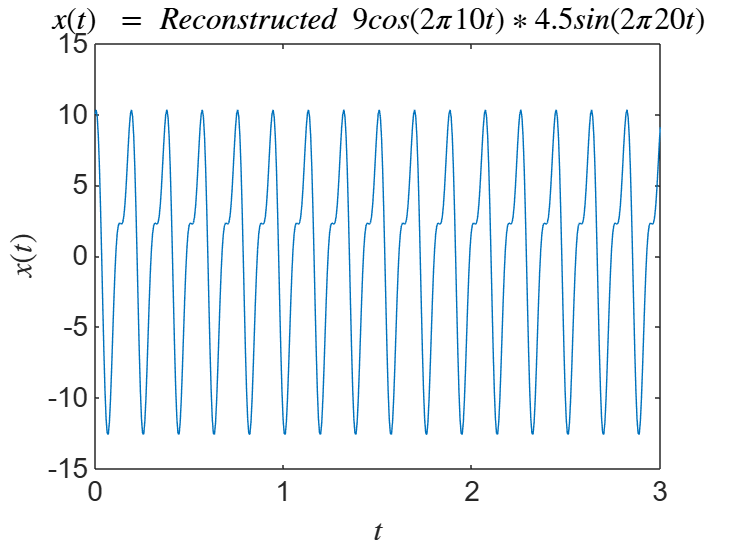


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ 9cos(2 \pi 10 t) * 4.5sin(2 \pi 20 t)$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')

## Part 4

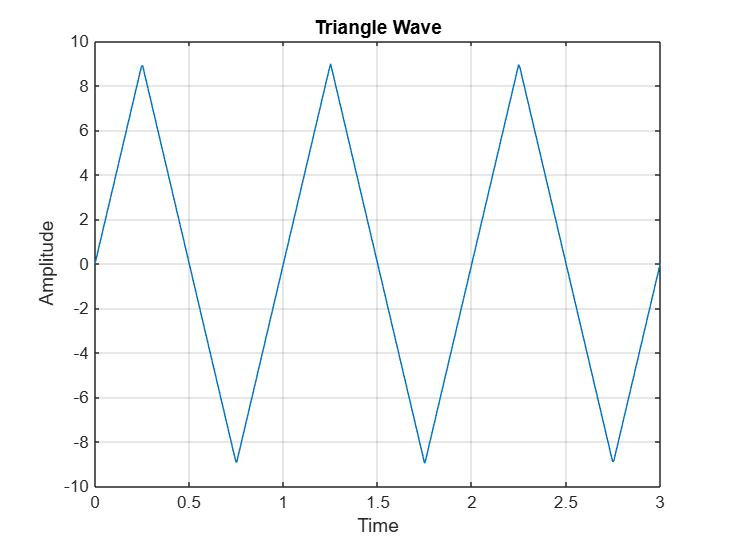

%% Generating the original signal
vec_size = 500;
f = 1;
fs = 32 * f;
t = linspace(0,(1/f)*3,vec_size); % x axis

x = A*sawtooth(2*pi*(t + f/4)* f,.5) ;

plot(t,x)
xlabel('Time');
ylabel('Amplitude');
title('Triangle Wave')
grid on

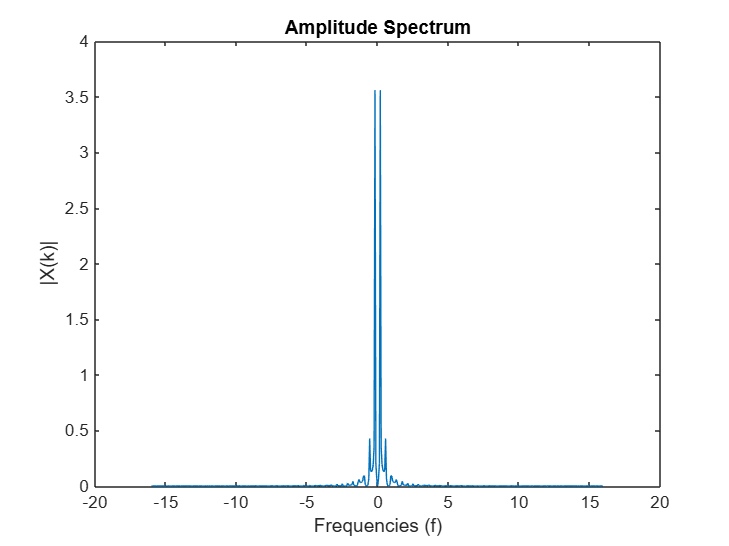


% Generating the amplitude spectrum
% FFTShift 
N = 512;
X = (1/N)*fft(x,N);
df = fs/N;

X1 = fftshift(X);
sampleIndex = -N/2:1:N/2-1;
f = sampleIndex*df;

plot(f,abs(X1))
title('Amplitude Spectrum')
xlabel('Frequencies (f)')
ylabel('|X(k)|')

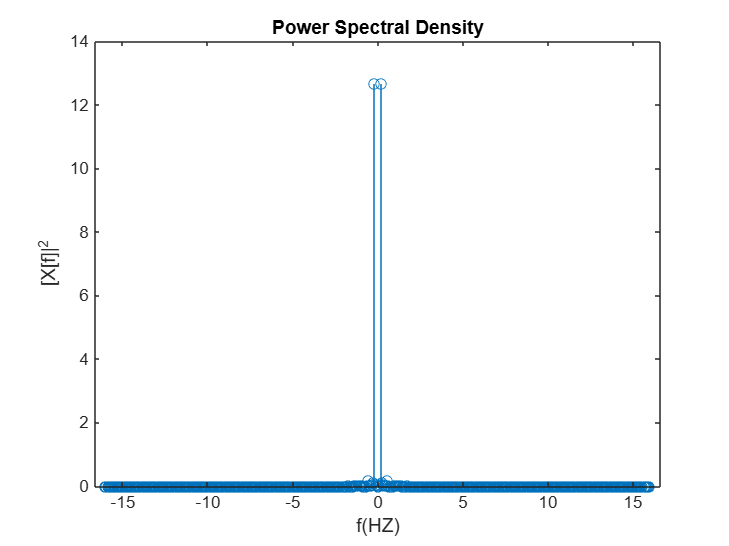


% Generating the power spectral density
stem(f,abs(X1).^2)
xlabel('f(HZ)')
ylabel('[X[f]|^2')
title('Power Spectral Density')

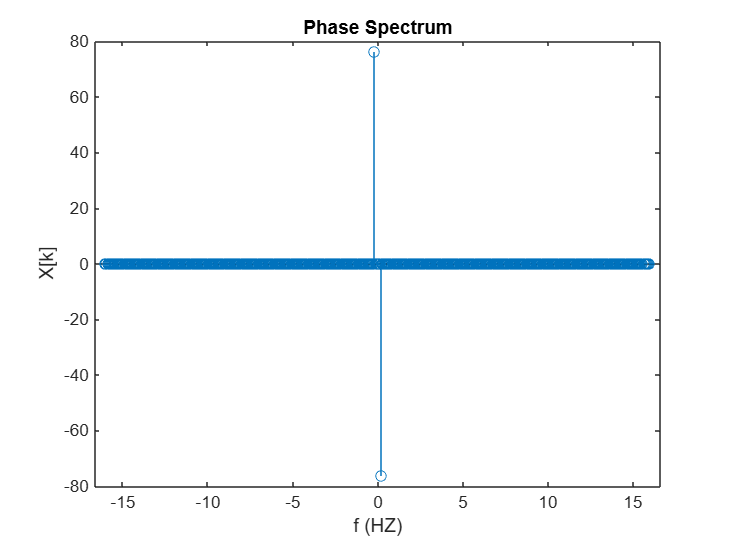



% Generating the phase spectrum
X2 = X1;
tol = max(abs(X1));
X2(abs(X1)<tol) = 0;
phase1 = atan2(imag(X2),real(X2));

stem(f,rad2deg(phase1))
ylabel('X[k]')
xlabel('f (HZ)')
title('Phase Spectrum')

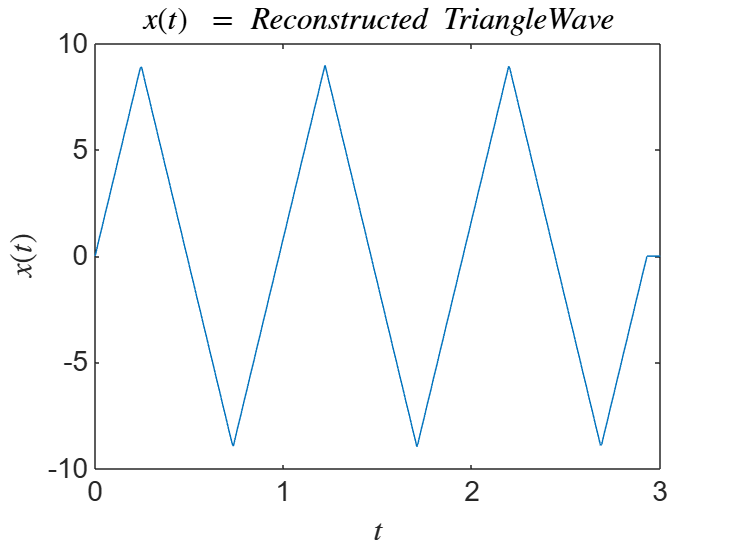


% Reconstructing the signal
X = N*ifftshift(X1);
x_recon = ifft(X,N);
T = linspace(0,3,N);

plot(T,x_recon)
set(gca,'fontsize',16)
title('$x(t)\ =\ Reconstructed\ Triangle Wave$','Interpreter','latex')
xlabel('$t$','Interpreter','latex')
ylabel('$x(t)$','Interpreter','latex')